## Define Experiment Parameters

%% Define where to look for rosbag files
project_root = "~/tagslam_ws/tagslam_root/src/continuum_mocap";
experiment_name = "planar_arm_wide";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
planar_arm_tags = [6 7 8 9 12 13 14]; % Tags 6 to 9 

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 1 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 25 30 35 40 45 50 60];
i_test_bag = 3;

## Retrieve Bag File

%% Find all bag files in bags dir corresponding to the desired experiment
%  that is specified by `experiment_name`
bags_dir = fullfile(project_root, "bags");

bag_files = dir(fullfile(bags_dir, experiment_name,'**/*.*'));  % Get list of files and folders in any subfolder
bag_files = bag_files(~[bag_files.isdir]);  % Remove folders from list

%% Search for localized(tagslammed) bags
% Create and fill selection mask
selection_mask = zeros(size(bag_files));
for i = 1 : length(bag_files)   
    if contains(bag_files(i).name, "localized")
        selection_mask(i) = 1;
    end
end
tagslam_bags = bag_files(logical(selection_mask)); % Apply selection mask

% Let's just test with the first bag file
bag = rosbag(fullfile(tagslam_bags(i_test_bag).folder, tagslam_bags(i_test_bag).name));

fprintf("Testing with bag: %s", tagslam_bags(i_test_bag).name)

Testing with bag: localized-25psi_2021-12-15-01-02-56.bag

## Extract and Plot Transformations

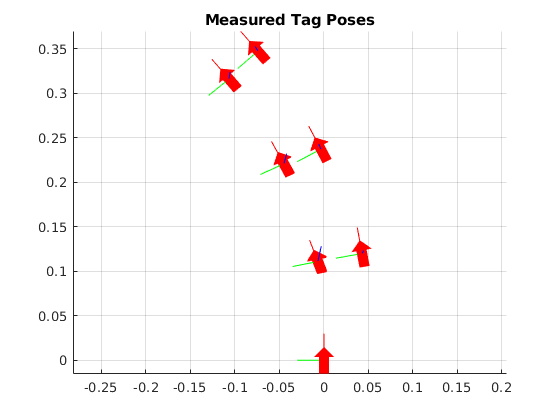

g_tags = cell(size(planar_arm_tags));
for i = 1 : length(planar_arm_tags)
    id_tag = planar_arm_tags(i);
    
    % Make sure that the tag we're looking for has an existing
    % transformation in the TF tree
    if ~any(bag.AvailableFrames == sprintf("tag_%d", id_tag))
        error("Tag with id %d not found in list of available frames", id_tag)
    end
    
    tform_i = getTransform(bag, "snake", "tag_" + id_tag);
    R = quat2rotm(tform_i.Transform.Rotation.readQuaternion());
    % Apply extra 90 deg ccw rotation to correct for misplaced tags
    R = R * eul2rotm([pi/2, 0, 0], 'zyx');
    
    T_obj = tform_i.Transform.Translation;
    T = [T_obj.X; T_obj.Y; T_obj.Z];
    g_tags{i} = SE3(R, T);
end

fig = figure();
ax = axes(fig);
grid on
axis equal

plot_options = struct();
plot_options.framesize = 0.03;
plot_options.MeshFilePath = "tf_frame.stl";
[gh_tforms, T_tforms, quat_tforms] = plotTransformsSE_n(g_tags, ax, plot_options);
view(0, 90)
title("Measured Tag Poses")

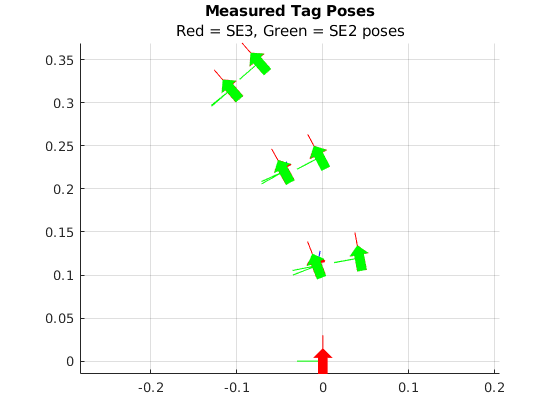

%% Reduce the full 3D pose of the tags to just a pose in SE2 since
%  we are just working with a 2d Planar Arm and can ignore pitch/roll or Z
g_tags_SE2 = cell(size(g_tags));
for i = 1 : length(g_tags)
    % Extract yaw values and create new SE2 g_tags
    eul_i = rotm2eul(g_tags{i}(1:3, 1:3), "zyx");
    theta = eul_i(1);
    
    x_y = g_tags{i}(1:2, 4);
    
    g_tags_SE2{i} = SE2(x_y(1), x_y(2), theta);
end

plot_options.meshcolor = "green";
plotTransformsSE_n(g_tags_SE2, ax, plot_options);
subtitle("Red = SE3, Green = SE2 poses")

## Create Arm Objects

%% Define arm geometry
rho = 1 * 0.0254; % m, Half of separator size
 
% Construct pose matrices
% Transform from world frame to base curve
g_1 = SE2(0, -base_offset_cm / 100, pi/2);

g_o_1 = SE2(0, rho, 0); % Muscle 1
g_o_2 = SE2(0, -rho, 0); % Muscle 2
g_o = g_1 * inv(g_o_1); % Central muscle
g_o_muscles = {g_1; g_o * g_o_2};

l_0 = contraction_fit(0); % Default length
model_arm =  Arm2D(g_o, g_o_muscles, l_0, 'plot_unstrained', false);
fit_arm = copy(model_arm);
fit_arm.muscles;

% Initialzie model arm:
psi = experiment_pressures(i_test_bag);
v_l = contraction_fit([psi; 0]);
h_o_model = model_arm.mat_N * v_l;

## Initialize Plotting

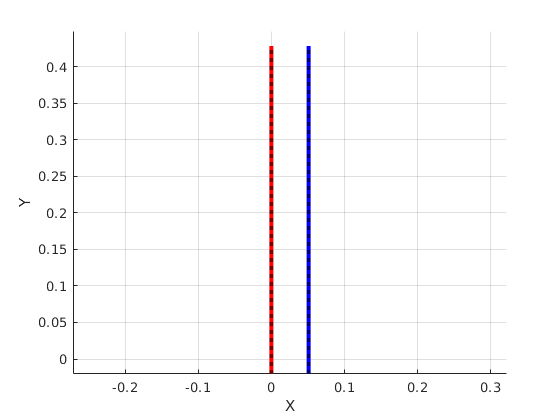

% Create figure
fig = figure();
ax = axes(fig);
grid on
axis equal

% Set plotting parameters
line_options_muscles = struct("LineWidth", 3);
line_options_spacers = struct("Linewidth", 2.5);
line_options_base_curve = struct("Linestyle", ":");

f_arm_initialize_plotting = @(arm) arm.initialize_plotting(ax, "line_options_muscles", line_options_muscles, ...
    "line_options_spacers", line_options_spacers, "line_options_base_curve", line_options_base_curve);

f_arm_initialize_plotting(model_arm);
f_arm_initialize_plotting(fit_arm);
fit_arm.muscle_o.color = 'green';

% Darken plotting colors in model arm
for i = 1 : length(model_arm.muscles)
    color_current = model_arm.muscles(i).color;
    model_arm.muscles(i).color = hsv2rgb(rgb2hsv(color_current) .* [1, 1, 0.5]);
    model_arm.muscles(i).lh.LineStyle = ":";
end

% Bring solid line (Fitted muscle curves) to the back
for i = 1 : length(fit_arm.muscles)
    uistack(fit_arm.muscles(i).lh, "bottom");
end

## Curve Fitting and Plotting

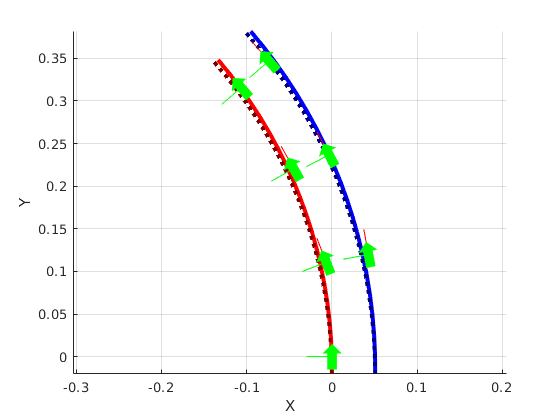

h_o_fit = curve_fit_2d(model_arm, g_tags_SE2, t_tags, muscle_ids, init_val=h_o_model);

model_arm.update_arm(v_l, h_o_model);
fit_arm.update_arm(v_l, h_o_fit);

model_arm.muscle_o.plot_muscle(ax, 'line_options', line_options_muscles);
fit_arm.muscle_o.plot_muscle(ax, 'line_options', line_options_muscles);

% Plot tag measurement transformations
plotTransformsSE_n(g_tags_SE2, ax, plot_options);